
Color_1 = [0 0.4470 0.7410];
Color_2 = [0.8500 0.3250 0.0980];
Color_3 = [0.9290 0.6940 0.1250];
Color_4 = [0.4940 0.1840 0.5560];
Color_5 = [0.4660 0.6740 0.1880];
Color_6 = [0.3010 0.7450 0.9330];
Color_7 = [0.6350 0.0780 0.1840];
Color_X = [0 0.4470 0.7410];
Color_Y = [0.8500 0.3250 0.0980];

%%

syms t x y mu real
f = [
    x*(1 - x/2) - x*y
    y*(mu - y) - x*y
    ]

$$f = \left(\begin{array}{c} -x\,\left(\frac{x}{2}-1\right)-x\,y\\ y\,\left(\mu -y\right)-x\,y \end{array}\right)$$

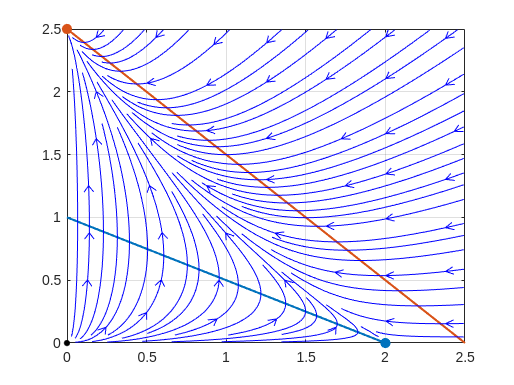

x = [x;y];

A = double(jacobian( simplify(f ./ x) , x ));
b = simplify( (f - A*x .* x) ./ x );

f_fh = matlabFunction(f,'vars',{x,mu});             % later used for ODE solver
J_fh = matlabFunction(jacobian(f,x),'vars',{x,mu}); % compute trace and determinant of Jacobian
f1_fh = matlabFunction(f(1),'vars',[x;mu]);         % to plot vector field
f2_fh = matlabFunction(f(2),'vars',[x;mu]);         % to plot vector field

A_ = num2cell(A');
[a11,a12,a21,a22] = deal(A_{:});
b1 = double(b(1));

%%

LimX = 2.5;
LimY = 2.5;
hX = 0.05;
hY = 0.05;

B = 0.3;
E = linspace(-B,B,101);
[x_,y_] = meshgrid(E,E);

fig = figure(3122);
for mu = 0.5:0.01:2.5
    b2 = mu;

    EqX = [-b1/a11 ; 0];
    EqY = [0 ; -b2/a22];
    EqP = -A\double(subs(b));

    hold off
    plot(0,0,'k.','MarkerSize',14);
    hold on, box on, grid on;

    xx = linspace(0,EqX(1),2);
    yy = -(b1+a11*xx)/a12;
    PlncX = plot(xx,yy,'Color',Color_X,'LineWidth',1.5);
    
    yy = linspace(0,EqY(2),2);
    xx = -(b2+a22*yy)/a21;
    PlncY = plot(xx,yy,'Color',Color_Y,'LineWidth',1.5);
    
    PleX = plot(EqX(1),EqX(2),'.','Color',Color_X,'MarkerSize',25);
    PleY = plot(EqY(1),EqY(2),'.','Color',Color_Y,'MarkerSize',25);
    PleP = plot(EqP(1),EqP(2),'.k','MarkerSize',14);
    
    [S,D] = eig(J_fh(EqP,mu));
    lambda = D(1,1);
    s = S(:,1);
    if lambda > 0
        lambda = D(2,2);
        s = S(:,2);
    end
    s_ = [s(2);-s(1)] * 0.025;
    s = s*0.2;

    points = EqP + [-s,s];
    points = [points + s_ , points - s_];

    % Compute the values of the vector field in a given number of grid points.
    [xx,yy] = meshgrid(0:hX:LimX,0:hY:LimY);
    f1_val = f1_fh(xx,yy,mu);
    f2_val = f2_fh(xx,yy,mu);
    
    % Normalize the vectors of the vector field.
    r = sqrt(f1_val.^2 + f2_val.^2);
    f1_val = f1_val ./ r;
    f2_val = f2_val ./ r;
    
    % Compute the values of the vector field in a given number of grid points.
    f1_ = f1_fh(x_+EqP(1),y_+EqP(2),mu);
    f2_ = f2_fh(x_+EqP(1),y_+EqP(2),mu);
    
    % Normalize the vectors of the vector field.
    r = sqrt(f1_.^2 + f2_.^2);
    f1_ = f1_ ./ r;
    f2_ = f2_ ./ r;
    
    % streamslice(xx,yy,f1_val,f2_val);

    if all(EqP > 0)
        verts = stream2(x_+EqP(1),y_+EqP(2),f1_,f2_,points(1,:),points(2,:));
        perc = {[30],[25 80],[25],[35 80]};
        P = zeros(0,2);
        Q = zeros(0,2);
        for i = 1:numel(verts)
            v = verts{i};
            idx = round(perc{i} / 100 * height(v));
            P = [P;v(idx,:)];
            Q = [Q;v(idx+1,:)];
        end
        arrow(P,Q,'BaseAngle',40,'Length',20)
        Sl = streamline(verts);
        for i = 1:numel(Sl)
            Sl(i).Color = 'black';
            Sl(i).LineWidth = 2;
        end
    end

    streamslice(xx,yy,f1_val,f2_val);
    % Sl = streamslice(x_+EqP(1),y_+EqP(2),f1_,f2_,0.5);
    % Sl.set('Color',Color_2);
    % plot(EqP(1)+[-B B B -B -B],EqP(2)+[-B -B B B -B],'Color',Color_2)

    % plot(points(1,:),points(2,:),'.')


    xlim([0 LimX])
    ylim([0 LimY])
    
    % 
    % verts = stream2(xx,yy,f1_val,f2_val)
    % streamline(verts)
    % 
    % fig = figure(3123);
    % delete(fig.Children)
    % ax = axes(fig);
    % hold on, grid on, box on
    % 
    % for i = 1:numel(verts)
    %     plot(verts{i}(:,1),verts{i}(:,2))
    %     plot(averts{i}(:,1),averts{i}(:,2))
    % end

    drawnow

end